%%% RBE 594 - Capstone Project Experience %%%
%%% Jason Munger %%%
clear
close all
clf

th = linspace(0,180,30);

rr= 2*1625*2;
PP1 = [rr*cos(deg2rad(th)); rr*sin(deg2rad(th))];
PP2 = [rr*ones(1,10);linspace(-rr,0,10)];
PP = [PP2(:,1:end-1), PP1]

PP = 	1.0e+03 *

    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.5000    6.4619    6.3480    6.1597    5.8992    5.5696    5.1746    4.7190    4.2080    3.6477    3.0447    2.4059    1.7389    1.0516    0.3519   -0.3519   -1.0516   -1.7389   -2.4059   -3.0447   -3.6477   -4.2080   -4.7190   -5.1746   -5.5696   -5.8992   -6.1597   -6.3480   -6.4619   -6.5000
   -6.5000   -5.7778   -5.0556   -4.3333   -3.6111   -2.8889   -2.1667   -1.4444   -0.7222         0    0.7028    1.3973    2.0755    2.7293    3.3511    3.9336    4.4700    4.9541    5.3800    5.7428    6.0383    6.2631    6.4144    6.4905    6.4905    6.4144    6.2631    6.0383    5.7428    5.3800    4.9541    4.4700    3.9336    3.3511    2.7293    2.0755    1.3973    0.7028    0.0000


% dist = []
% for i = 1:length(PP)-1
%     d = calcDistance(PP(:,i),PP(:,i+1));
%     dist = [dist,d];
% end
% dist
% remove = mod(length(PP)-1,2)
% idx = find(dist<1500)
% a = length(PP) - length(idx(2:2:end))
% remove = mod(a-1,2)
% PP(:,idx(2:2:end)) = []
% % PP(:,end-1) = []
% dist = []
% for i = 1:length(PP)-1
%     d = calcDistance(PP(:,i),PP(:,i+1));
%     dist = [dist,d];
% end
% dist
% idx = find(dist<1500)
% a = length(PP) - length(idx(2:2:end))
% remove = mod(a-1,2)
% PP(:,idx(2:2:end)) = []
% dist = []
% for i = 1:length(PP)-1
%     d = calcDistance(PP(:,i),PP(:,i+1));
%     dist = [dist,d];
% end
% dist
% PP = flip(PP,2)
% PP = flip(PP,1)

M = [[40; 2], [40; 3], [40; 4], [40; 5], [40; 6], [40; 7], [40; 8], [40; 9], [40; 10], [40; 11], [40; 12], [40; 13], [40; 14], [40; 15], [40; 16], [40; 17], [40; 18], [40; 19], [40; 20], [40; 21], [40; 22], [40; 23], [40; 24], [40; 25], [40; 26], [40; 27], [40; 28], [40; 29], [39; 29], [39; 30], [39; 31], [39; 32], [39; 33], [39; 34], [39; 35], [39; 36], [39; 37], [39; 38], [39; 39], [39; 40], [39; 41], [39; 42], [39; 43], [39; 44], [39; 45], [39; 46], [39; 47], [39; 48], [39; 49], [39; 50], [39; 51], [39; 52], [38; 52], [37; 52], [37; 53], [36; 53], [35; 53], [34; 53], [33; 53], [32; 53], [31; 53], [31; 54], [30; 54], [29; 54], [28; 54], [27; 54], [26; 54], [25; 54], [24; 54], [23; 54], [22; 54], [21; 54], [20; 54], [19; 54], [18; 54], [17; 54], [16; 54], [15; 54], [14; 54], [13; 54], [12; 54], [11; 54], [10; 54], [9; 54], [8; 54], [7; 54], [6; 54], [5; 54], [4; 54], [3; 54], [2; 54]];
% 
% M = M(:,1:4:end)



% M = M(:,1:end-remove)
% % M = M(:,1:end-2)
% % 
M = M*300;
N = PP;
% N = M;
P = [];
P = [P,N(:,1)];
[~,c] = size(N);
while c > 1
    d = calcDistance(N(:,1), N(:,2));
    if d > 750
        P = [P,N(:,2)];
        N(:,1) = [];
        [~,c] = size(N);
    else
        N(:,2)=[];
        [~,c] = size(N);
    end
end

if isequal(PP(:,end),P(:,end))
    disp('true')
else
    P = [P,(PP(:,end))];
end

true


% if isequal(M(:,end),P(:,end))
%     disp('true')
% else
%     P = [P,(M(:,end))];
% end
if mod(length(P)-1,2) >0
    pp = (P(:,end)+P(:,end-1))/2;
    P = [P(:,1:end-1), pp, P(:,end)];
end
P

P = 	1.0e+03 *

    6.5000    6.5000    6.5000    6.5000    6.5000    6.4619    6.1597    5.5696    4.7190    3.6477    2.4059    1.0516   -0.3519   -1.7389   -3.0447   -4.2080   -5.1746   -5.8992   -6.3480   -6.4240   -6.5000
   -6.5000   -5.0556   -3.6111   -2.1667   -0.7222    0.7028    2.0755    3.3511    4.4700    5.3800    6.0383    6.4144    6.4905    6.2631    5.7428    4.9541    3.9336    2.7293    1.3973    0.6987    0.0000


% P = flip(P,1)
% P = flip(P,2)
% P = flip(P,1)
L = 750

L = 750

v = 1500

v = 1500

B = 0.5

B = 0.5000

rr = 3250

rr = 3250

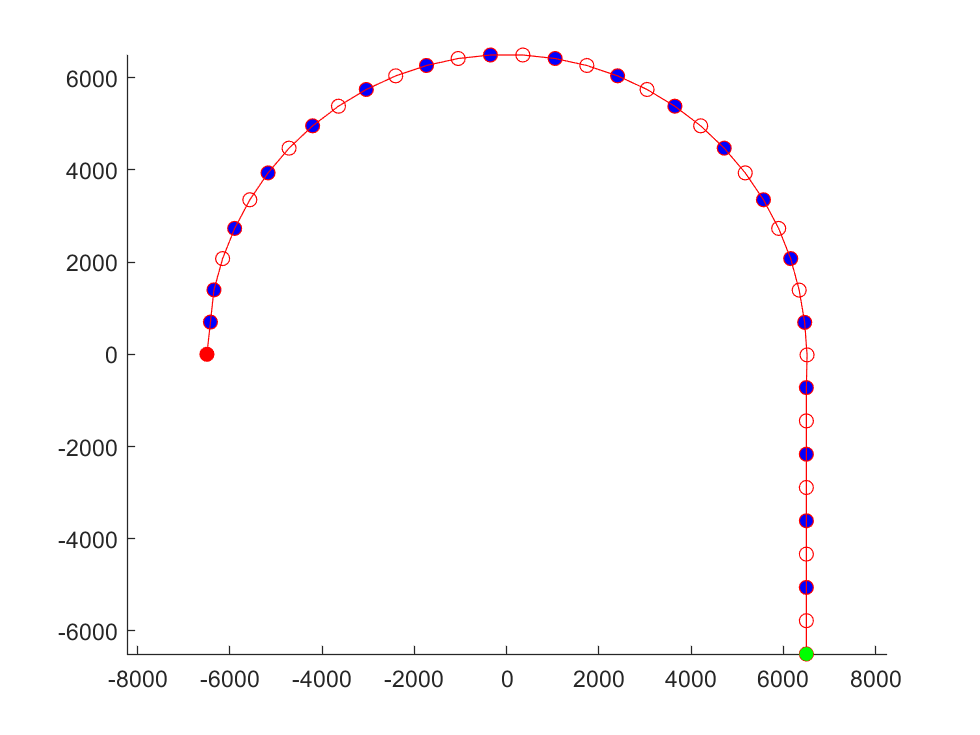

% waypoints = [rr+rr-1000 rr+rr*cosd(45)-1000 rr+rr*cosd(90) (rr+500)*cosd(135) -(rr+500); 0 rr*sind(45) rr*sind(90) rr+500+rr*sind(135) rr+500+rr ]
% waypoints = flip(waypoints,2)
waypoints = P;
n = (length(waypoints)-1)/2;
j = 1;
thd = pi/2;
th0 = pi/2;
N_steps = 0;
Ltotal = 0;
Ttotal = 0;
% th_start = 0
Xdes = [waypoints(:,1);th0];
% Xdes = [waypoints(:,1);th0]
for i = 1:n
    i;
    P0 = waypoints(:,2*i-1);
    P1 = waypoints(:,2*i);
    P2 = waypoints(:,2*i+1);
%     d = rotDirection(P0,P2)
    [xc, yc, R] = findCircle(P0,P1,P2);
    R;
    PP2 = P2-[xc;yc];
    PP0 = P0-[xc;yc];
%     PP2 = [xc;yc]-P2
%     PP0 = [xc;yc]-P0
     t2 = atan2(PP2(2),PP2(1));
     t0 = atan2(PP0(2),PP0(1));
     theta = abs(t2-t0);
     dir = sign(t2-t0);
%     t2 = atan2(P2(2)-yc,P2(1)-xc)
%     tt = sign(th2-th0)
%     theta = acos(1-(((PP2(1)-PP0(1))^2 + (PP2(2)-PP0(2))^2)/(2*R^2)))
%     th2 = th0 + theta
%     th2 = atan2(P2(2),P2(1))
%     theta = th2-th0
   
    S = abs(R*theta);
    num_steps = ceil(S/L);
    Lmax = S/num_steps;
    Tcyc = Lmax/v;
    Tseg = num_steps*Tcyc;
    ths = B*Lmax/R;
    wd = dir*ths/(B*Tcyc);
%     th0 = th2
    dx = P0(1)-xc;
    dy = P0(2)-yc;
    ang = atan2(dy,dx);
%     if ang <0
%         ang = ang + 2*pi
%     end
%     offset = ang-rad2deg(th_start)
    
    for t = Tcyc:Tcyc:Tseg
    
    thd = th0 + wd*t;
%     th_start = th0
%     th_start + dir*wd*t
% wd*t;
    Xdes(:,j+1) = [xc + R*cos(ang + wd*t); yc + R*sin(ang + wd*t); thd];
    Ldes(j) = Lmax;
    Rdes(j) = R;
    Xcdes(:,j) = [xc;yc];
    j = j + 1;
    
    end 
%     N_steps = N_steps + num_steps;
%     Ltotal = Ltotal + Lmax * num_steps;
%     Ttotal = Ttotal + Tseg;
    th0 = thd;
%     th_start = -wd*Tseg
%     plotCircle(R,0,xc,yc,'k')
%     hold on
%     scatter(xc, yc)
end
% Ltotal
% Ttotal
% vcheck = Ltotal/Ttotal
scatter(waypoints(1,:),waypoints(2,:),'b','filled')
hold on
scatter(Xdes(1,:),Xdes(2,:),'r')
plot(Xdes(1,:),Xdes(2,:),'r')
scatter(Xdes(1,1),Xdes(2,1),'g', "filled")
scatter(Xdes(1,end),Xdes(2,end),'r', "filled")
axis equal
view([0.00 90.00])

% xlim([-10000,20000])
% ylim([-10000,20000])

function [xc, yc, R] = findCircle(P0,P1,P2)
    x0 = P0(1);
    x1 = P1(1);
    x2 = P2(1);
    y0 = P0(2);
    y1 = P1(2);
    y2 = P2(2);
    
    m01 = round((y1-y0)/(x1-x0),4);
    m12 = round((y2-y1)/(x2-x1),4);
    
    if (x0 == x1) || (x1 == x2) && (m01||m12 == -Inf)
        R = 1e12;
        xc = x0 - R;
        yc = y0;
    elseif (x0 == x1) || (x1 == x2)
        R = 1e12;
        xc = x0 + R;
        yc = y0;

    elseif m01 == m12
        R = 1e12;
        tht = atan2((y1-y0),(x1-x0));
        xc = x0 -R*sin(tht) ;
        yc = y0 +R*cos(tht);
    
    else
        M = [2*x0 2*y0 1;
            2*x1 2*y1 1;
            2*x2 2*y2 1];

        N = [-(x0^2+y0^2);
            -(x1^2+y1^2);
            -(x2^2+y2^2)];

        C = M\N;

        xc = round(-C(1),4);
        yc = round(-C(2),4);
        R = sqrt(xc^2+yc^2-C(3));
    end
    
   
end

function plotCircle(Rm,h,xc,yc,color)
    th = linspace(0,360,500);
    cir_x = Rm*cosd(th)+xc;
    cir_y = Rm*sind(th)+yc;
    cir_z = h*ones(length(cir_x),1)';
    plot3(cir_x,cir_y, cir_z,"Color",color,"LineWidth",1,'LineStyle','--')
end

function d = rotDirection(P0,P1)
%     aa = atan(P0(2)/P0(1))
%     bb = atan(P1(2)/P1(1))
%     if aa ==pi
%         aa = aa + 2*pi
%     end
%     aa
%     bb = bb + 2*pi
%     if aa < 0
%         aa = aa + 2*pi
%     end
%     if bb < 0
%         bb = bb + 2*pi
%     end
%     cc = bb-aa
    cc = cross([P0;0],[P1;0]);

    d = sign(cc(3));
    if d == 0
        if (P1(2)-P0(2))>0
            d = -1;
        else
            d = 1;
        end
    end
end

function d = calcDistance(P0,PP)
%     x = PP(1,:);
%     y = PP(2,:);
    d = sqrt((PP(1,:)-P0(1,:)).^2 + (PP(2,:)-P0(2,:)).^2);
end